[ispc isunix]

ans = 1×2 logical array
   1   0


% set cwd
if ispc
    % Code to run on Windows platform
    homedir = fullfile('G:','My Drive','MATLAB');
    audiodir = fullfile(homedir,'Audio');
    HMD_dir = fullfile(audiodir,'HMD_ID')
    cd(HMD_dir);
    currentFolder = pwd
    datapath="D:\MatlabData\HMD\audio_flat_10s"
elseif isunix
    % Code to run on Linux platform
    homedir = '/home/ganesh/GoogleDrive/MATLAB';
    audiodir = append(homedir,"/Audio");
    cd(audiodir);
    currentFolder = pwd
    datapath="/home/ganesh/matlab_r2021b/data_is_here/RagaID";
else
    disp('Platform not supported')
end

HMD_dir = 'G:\My Drive\MATLAB\Audio\HMD_ID'

currentFolder = 'G:\My Drive\MATLAB\Audio\HMD_ID'

datapath = "D:\MatlabData\HMD\audio_flat_10s"



% create AudioDatastore
ADS = audioDatastore(datapath,"IncludeSubfolders",true,"LabelSource","Foldernames",'FileExtensions','.wav')

ADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_00_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_01_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_02_10swav.wav'
                               ... and 1881 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 1881 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


shuffledADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi5_001SR_13_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi3_001SR_41_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Basant\Basant57_00SR_43_10swav.wav'
                               ... and 1881 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Basant ... and 1881 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


if ~isempty(ver('parallel'))
    pool = gcp;
    numPar = numpartitions(ADS,pool)
else
    numPar = 1
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


numPar = 18

**split ADS to training, validation and test data sets**

rng default;
shuffledADS = shuffle(ADS)

shuffledADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi5_001SR_13_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi3_001SR_41_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Basant\Basant57_00SR_43_10swav.wav'
                               ... and 1881 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Basant ... and 1881 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[trainADS,valADS,testADS] = splitEachLabel(shuffledADS,0.8,0.1)

trainADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi5_001SR_13_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi3_001SR_41_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Basant\Basant57_00SR_43_10swav.wav'
                               ... and 1504 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Basant ... and 1504 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


valADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi7_000SR_52_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi4_000SR_05_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi8_000SR_03_10swav.wav'
                               ... and 186 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 186 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi2_003SR_08_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi5_000SR_14_10swav.wav';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi7_000SR_20_10swav.wav'
                               ... and 185 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 185 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


disp(countEachLabel(trainADS))

    Label     Count
    ______    _____

    Abhogi     823 
    Basant     684 



disp(countEachLabel(valADS))

    Label     Count
    ______    _____

    Abhogi     103 
    Basant      86 



## create Spectrogram with transform on data

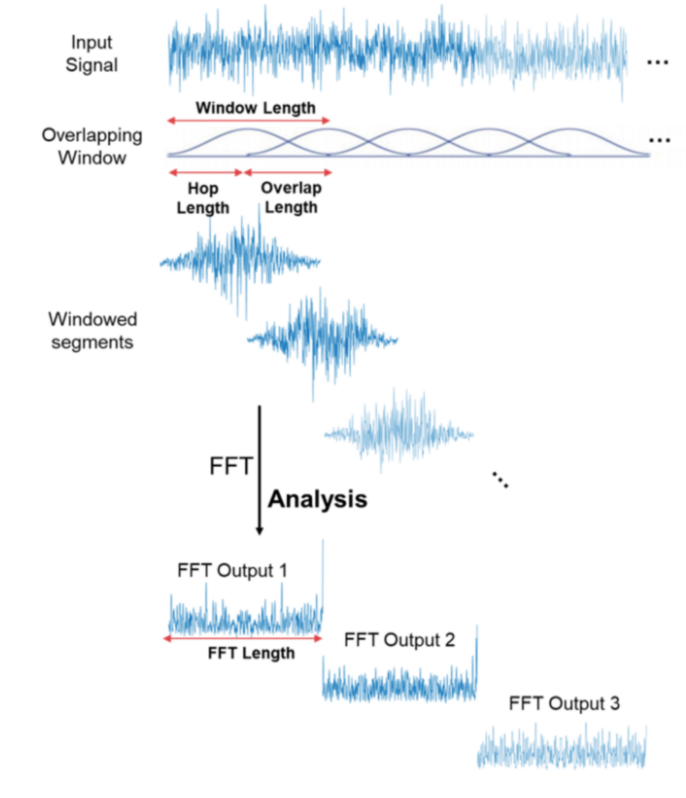

trainADS.reset;valADS.reset;testADS.reset;
%ADS.reset;

segmentDuration = 10; %4 second audio .mp3 file 
frameDuration = 0.025; %duration of hanning/hamming window
hopDuration = 0.01; %see diagram below
numBands = 32; %number of mel filer banks, i think..


fileDuration_sec = 10;
windowLength_frames = 2048;
numOverlap_frames = 1024;
numFFT = 2048;
% get num_rows, num_cols for 1 10s mp3
[x, info] = read(trainADS)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


info = struct with fields:
    SampleRate: 44100
      FileName: 'D:\MatlabData\HMD\audio_flat_10s\Basant\Basant55_00SR_26_10swav.wav'
         Label: Basant


 x = x(:,1);
 fs = info.SampleRate;
 s = spectrogram(x,windowLength_frames,numOverlap_frames,numFFT,fs)

s = 	1.0e+02 *

  -0.0000 + 0.0000i   0.0021 + 0.0000i   0.0112 + 0.0000i  -0.0020 + 0.0000i   0.0029 + 0.0000i   0.0022 + 0.0000i  -0.0026 + 0.0000i   0.0026 + 0.0000i  -0.0028 + 0.0000i   0.0009 + 0.0000i   0.0011 + 0.0000i  -0.0002 + 0.0000i  -0.0005 + 0.0000i  -0.0014 + 0.0000i  -0.0023 + 0.0000i  -0.0011 + 0.0000i  -0.0008 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0005 + 0.0000i   0.0036 + 0.0000i   0.0004 + 0.0000i  -0.0025 + 0.0000i   0.0020 + 0.0000i   0.0008 + 0.0000i  -0.0009 + 0.0000i   0.0017 + 0.0000i  -0.0010 + 0.0000i   0.0027 + 0.0000i  -0.0028 + 0.0000i   0.0009 + 0.0000i  -0.0005 + 0.0000i  -0.0042 + 0.0000i  -0.0010 + 0.0000i   0.0034 + 0.0000i   0.0041 + 0.0000i  -0.0018 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0013 + 0.0000i   0.0003 + 0.0000i  -0.0022 + 0.0000i   0.0006 + 0.0000i  -0.0000 + 0.0000i  -0.0003 + 0.0000i   0.0000 + 0.0000i   0.0016 + 0.0000i   0.0018 + 0.0000i  -0.0004 + 0.0000i   0.0007 + 0.0000i
  -0.0000 - 0.0000i  -0.0005 - 0.

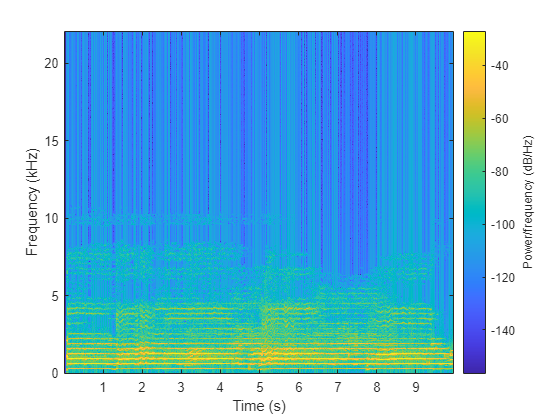

spectrogram(x,windowLength_frames,numOverlap_frames,numFFT,fs,'yaxis')

z= melSpectrogram(x,fs)

z =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

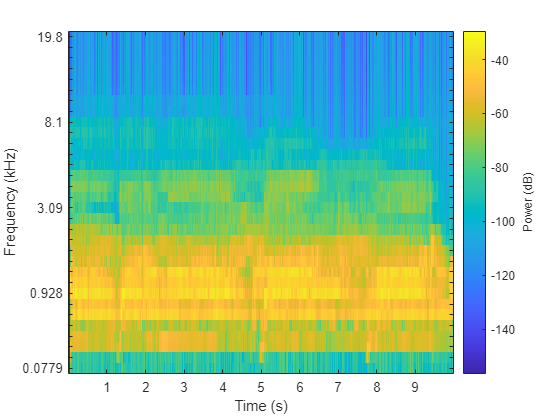


 melSpectrogram(x,fs)

[numBands,numFrames] = size(z)

numBands = 32

numFrames = 998

trainADS.reset;valADS.reset;testADS.reset;
%ADS.reset;

fprintf('----- Extracting XTrain Spectrograms.\n');

----- Extracting XTrain Spectrograms.


XTrain = getMelSpectrogram(trainADS,segmentDuration,frameDuration,hopDuration,numBands,numPar,numFFT);
XTrain = log10(XTrain + eps);
[numBands,numHops,numChannels,numSpec] = size(XTrain)

numBands = 32

numHops = 998

numChannels = 1

numSpec = 1507

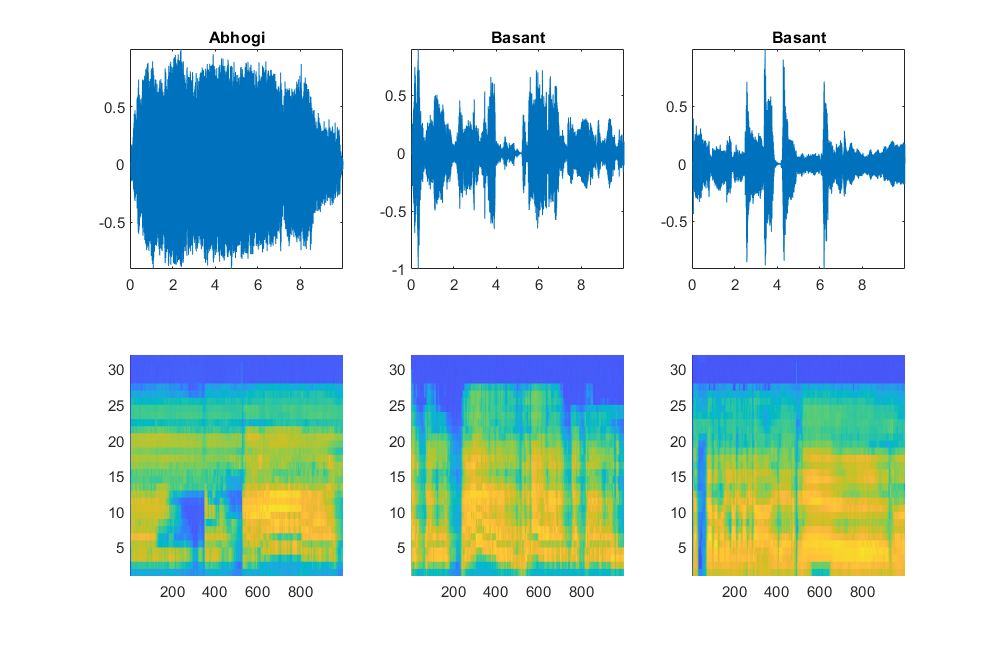

specMin = min(XTrain,[],'all');
specMax = max(XTrain,[],'all');
idx = randperm(size(XTrain,4),3);
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6])
for i = 1:3
    [x,fs] = audioread(trainADS.Files{idx(i)});
    sound(x,fs)
    subplot(2,3,i)
    N = length(x);
    t = (0:N-1)/fs;
    plot(t,x(:,1))
    axis tight
    %title(string(trainADS.Labels(idx(i))), M(trainADS.Labels(idx(i))))
    title(string(trainADS.Labels(idx(i))))
    %title(urban8k_table.class(idx(i)))
    
   
    subplot(2,3,i+3)
    spect = (XTrain(:,:,1,idx(i)));
    pcolor(spect)
    caxis([specMin specMax])
    shading flat

    
    pause(segmentDuration+1)
    
end

fprintf('++++ Extracting XVal MelSpecs.\n');

++++ Extracting XVal MelSpecs.


XValidation = getMelSpectrogram(valADS,segmentDuration,frameDuration,hopDuration,numBands,numPar,numFFT);
XValidation = log10(XValidation + eps);
[numBands,numHops,numChannels,numSpec] = size(XValidation)

numBands = 32

numHops = 998

numChannels = 1

numSpec = 189

fprintf('$$$$ Extracting XTest MelSpecs.\n');

$$$$ Extracting XTest MelSpecs.


XTest = getMelSpectrogram(testADS,segmentDuration,frameDuration,hopDuration,numBands,numPar,numFFT);
XTest = log10(XTest + eps);
[numBands,numHops,numChannels,numSpec] = size(XTest)

numBands = 32

numHops = 998

numChannels = 1

numSpec = 188

fprintf('$$$$ Done Extracting XTest MelSpecs.\n');

$$$$ Done Extracting XTest MelSpecs.


YTrain = trainADS.Labels;
YValidation = valADS.Labels;
YTest = testADS.Labels;

[numBands numHops numChannels numSpecs] = size(XTrain)

numBands = 32

numHops = 998

numChannels = 1

numSpecs = 1507

class(YTrain)

ans = 'categorical'

YTrain = categorical(YTrain);
class(YTrain)

ans = 'categorical'

sz = size(XTest);
specSize = sz(1:2);
imageSize = [specSize 1]

imageSize =     32   998     1



numClasses = numel(categories(Ytest))

numClasses = 2

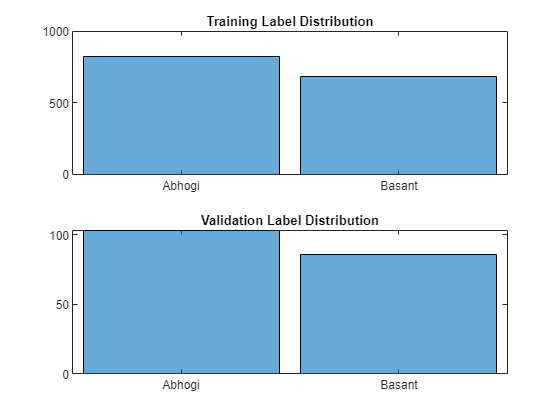

%figure('Units','normalized','Position',[0.2 0.2 0.5 0.5])

subplot(2,1,1)
histogram(YTrain)
title("Training Label Distribution")

subplot(2,1,2)
histogram(YValidation)
title("Validation Label Distribution")


dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer(imageSize,'Normalization','none')

    convolution2dLayer(5,numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2)

    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer('Classes',categories(YTest));
    ]

layers =   24×1 Layer array with layers:

     1   ''   Image Input             32×998×1 images
     2   ''   Convolution             12 5×5 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             3×3 max pooling with stride [2  2] and padding 'same'
     6   ''   Convolution             24 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             3×3 max pooling with stride [2  2] and padding 'same'
    10   ''   Convolution             48 3×3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU
    13   ''   Max Pooling             3×3 max poolin

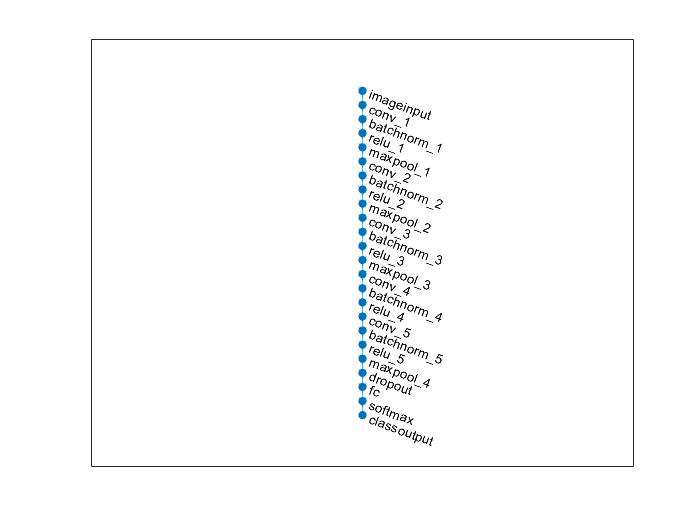

numClasses = 2

layers =   24×1 Layer array with layers:

     1   'Input'   Image Input             32×998×1 images with 'zerocenter' normalization
     2   ''        Convolution             12 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''        Batch Normalization     Batch normalization
     4   ''        ReLU                    ReLU
     5   ''        Max Pooling             3×3 max pooling with stride [2  2] and padding 'same'
     6   ''        Convolution             24 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''        Batch Normalization     Batch normalization
     8   ''        ReLU                    ReLU
     9   ''        Max Pooling             3×3 max pooling with stride [2  2] and padding 'same'
    10   ''        Convolution             48 3×3 convolutions with stride [1  1] and padding 'same'
    11   ''        Batch Normalization     Batch normalization
    12  

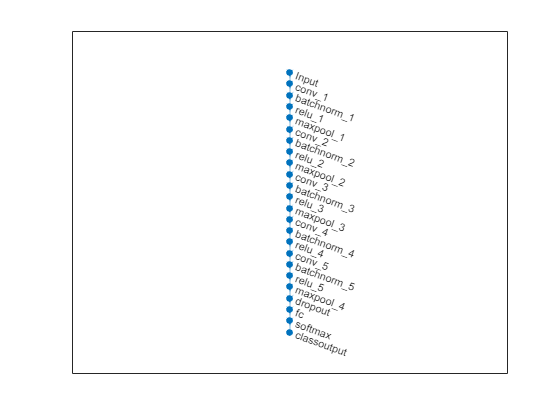

lgraph = layerGraph(layers);
figure
plot(lgraph)

miniBatchSize = 8;
initialLearnRate = 0.000001;
maxEpochs = 500;
options = trainingOptions('adam', ...
    'InitialLearnRate',initialLearnRate, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{XTest, YTest},...
    'ValidationFrequency',ceil(numel(adsTrain.Files)/miniBatchSize),...
    'ExecutionEnvironment','gpu');
% options = trainingOptions('adam', ...
%     'InitialLearnRate',initialLearnRate, ...
%     'MaxEpochs',maxEpochs, ...
%     'LearnRateSchedule',"piecewise",...
%     'LearnRateDropFactor',.1,...
%     'LearnRateDropPeriod',15,...
%     'MiniBatchSize',miniBatchSize, ...
%     'Shuffle','every-epoch', ...
%     'Plots','training-progress', ...
%     'Verbose',false, ...
%     'ValidationData',{XTest, YTest},...
%     'ValidationFrequency',ceil(numel(adsTrain.Files)/miniBatchSize),...
%     'ExecutionEnvironment','gpu');

trainedNet = trainNetwork(XTrain,YTrain,layers,options)

function XOutC = getSpectrogram(audioIn_ds,windowLength_frames,numOverlap_frames,numFFT,numPar)
% spectrogram for 1 channel
%s = spectrogram(x,window,noverlap,nfft) uses nfft sampling points to calculate the discrete Fourier transform.
% returns the short-time Fourier transform of the input signal, x. 
% Each column of s contains an estimate of the short-term, 
% time-localized frequency content of x.

% Using MATLAB's spectrogram
% The syntax is spectrogram(x,window,overlap,NFFT,fs)
% where
% x
%       is your entire data vector
% window 
%       is your window function. 
%       If you enter just a number, say W (must be integer), 
%       then MATLAB chops up your data into chunks of W samples each and forms the spectrogram from it. 
%       This is equivalent to using a rectangular window of length W samples. 
%       If you want to use a different window, provide hann(W) or whatever window you choose.
% overlap
%       is the number of samples that you need to overlap. So, if you need 50% overlap, this value should be W/2. 
% Use floor(W/2) or ceil(W/2) if W can take odd values. This is just an integer.
% NFFT 
%      is the FFT length
% fs 
%       is the sampling frequency of your data vector.
%       You can leave this empty, and MATLAB plots the figure in terms of normalized frequencies and the time axis as simply the data chunk index. 
%       If you enter it, MATLAB scales the axis accordingly.
    
    numFiles = length(audioIn_ds.Files)
    XoutC = []
    for i = 1:1
    %for i = 1:length(numFiles.Files)
        %fprintf("subds # : %d \n",i)
        [x, info] = read(audioIn_ds);
        x = x(:,1);
        fs = info.SampleRate;
        XOutC{i} = spectrogram(x,windowLength_frames,numOverlap_frames,numFFT)
    end

end



function XOutC = getMelSpectrogram(audioIn_ds,segmentDuration,frameDuration,hopDuration,numBands,numPar,numFFT)
% Mel spectrogram, returned as a column vector, matrix, or 3-D array. 
% The dimensions of S are L-by-M-by-N, where:
% L is the number of frequency bins in each mel spectrum. 
% NumBands and fs determine L.
% M is the number of frames the audio signal is partitioned into. 
% size(audioIn,1), WindowLength, and OverlapLength determine M.
% N is the number of channels such that N = size(audioIn,2)
%Trailing singleton dimensions are removed from the output S.

    % disp("Computing mel spec with padding..");
    numFiles = length(audioIn_ds.Files);
    numHops = ceil((segmentDuration-frameDuration)/hopDuration);
    %numHops =343;
    XOutC = zeros([numBands,numHops,1,numFiles],'single');
parfor ii = 1:numPar
    %fprintf("numPar # : %d \n",ii)
    subds = partition(audioIn_ds,numPar,ii);
    
    XOut = zeros([numBands,numHops,1,numel(subds.Files)],'single');
    A = size(XOut);
    for i = 1:length(subds.Files)
        %fprintf("subds # : %d \n",i)
        [x, info] = read(audioIn_ds);
        x = x(:,1);
        fs = info.SampleRate;
        segmentSamples = round(segmentDuration*fs); %# of samples in full clip
        frameSamples   = round(frameDuration*fs); % # of samples in window length. here is 1102,close to 1024
        hopSamples     = round(hopDuration*fs); % usually half of frameSamples. so here its 550
        overlapSamples = frameSamples - hopSamples;
        FFTLength      = numFFT; %should be greater than equal to segmentSamples
        XPadded        = PadX(x,segmentSamples);
    
        melSpec = melSpectrogram(XPadded,fs, ...
                   'OverlapLength',overlapSamples, ...
                   'FFTLength',FFTLength, ...
                   'NumBands',numBands, ...
                   'Window',hann(frameSamples,'periodic'));
        
        w = size(melSpec,2);
        %w can be <,==,> numHops
        %if <, then do 
        if (w < numHops)
            left = floor((numHops-w)/2)+1;
            ind = left:left+w-1;
            %fprintf("** w %d < NumHops %d at %d \n",w,numHops,i)
            XOut(:,ind,1,i) = melSpec;
        elseif (w > numHops)
            %fprintf("++ w %d > NumHops %d at %d \n",w,numHops,i)
            XOut(:,:,1,i) = melSpec(:,(1:numHops));
        else
            XOut(:,:,1,i) = melSpec;
        end
        if mod(i,1000) == 0
            fprintf('%d th spectrogram extracted.\n',i);
        end
    end
    %fprintf('%d th XoutC done.\n',ii);
    XOutA{ii} = XOut;
    
end
XOutC = cat(4,XOutA{:});
XoutCSize = size(XOutC);
end 


function [XPadded] = PadX(x,segmentSamples)
    numSamples = size(x,1);
    numToPadFront = floor( (segmentSamples - numSamples)/2 );
    numToPadBack = ceil( (segmentSamples - numSamples)/2 );
    XPadded = [zeros(numToPadFront,1,'like',x);x;zeros(numToPadBack,1,'like',x)];
end   